# **Esercitzione n*3 - Stima modelli ingresso uscita**

## Descrizione del problema

E' stato condotto un esperimento per valutare la cinetica del C-peptide (un peptide secreto insieme all'insulina) in 7 soggetti misurando la risposta ad un bolo di C-peptide sintetico. L'esperimento prevede una misura al tempo 0 (prima del bolo) per determinare il valore della concentrazione basale. La misura effettuata al minuto 1 non e' da considerare (e deve essere trascurata nell'identificazione del modello) in quanto ci sono buone ragioni per affermare cha a quel tempo la concentrazione plasmatica non e' uniforme (la sostanza non si e' ancora distribuita nell'intero compartimento plasmatico - problemi di mescolamento). Le misure di concentrazione sono affette da un errore di misura caratterizzato da un CV del 4%. Come esercizio e in via esploratoria, identificare su i dati di almeno un soggetto i modelli a 1,2,3 esponenziali utilizzandp la tecnica dei minimi quadrati e dei minimi quadrati pesati (con peso pari all'inverso della varianza dell'errore di misura). 

clearvars;
clc;

## Lettura dei dati 

I dati sono relativi a 7 soggetti diversi e contenuti nei file` DatiCPSog1.dat`, `DatiCPSog2.dat, ecc.`

% Importazione dei dati 
d_sog1 = importdata("DatiCPsog1.dat");
d_sog2 = importdata("DatiCPsog2.dat");
d_sog3 = importdata("DatiCPsog3.dat");
d_sog4 = importdata("DatiCPsog4.dat");
d_sog5 = importdata("DatiCPsog5.dat");
d_sog6 = importdata("DatiCPsog6.dat");
d_sog7 = importdata("DatiCPsog7.dat");

Dal momento che i dati letti attraverso la funzione `importdata `sono organizzati in una struttura che richiederebbe molte operazioni, si memorizzano le informazioni in semplici array. Tale procedura consente di effettuare in agilita' le successive operazioni di data cleaning.

% Data retrieval
dose1 = str2num(d_sog1.textdata{1,2});
t1 = str2num(cell2mat(d_sog1.textdata(4:end,1)));
c1 = str2num(cell2mat(d_sog1.textdata(4:end,2)));

dose2 = str2num(d_sog2.textdata{1,2});
t2 = str2num(cell2mat(d_sog2.textdata(4:end,1)));
c2 = str2num(cell2mat(d_sog2.textdata(4:end,2)));

dose3 = str2num(d_sog3.textdata{1,2});
t3 = str2num(cell2mat(d_sog3.textdata(4:end,1)));
c3 = str2num(cell2mat(d_sog3.textdata(4:end,2)));

dose4 = str2num(d_sog4.textdata{1,2});
t4 = str2num(cell2mat(d_sog4.textdata(4:end,1)));
c4 = str2num(cell2mat(d_sog4.textdata(4:end,2)));

dose5 = str2num(d_sog5.textdata{1,2});
t5 = str2num(cell2mat(d_sog5.textdata(4:end,1)));
c5 = str2num(cell2mat(d_sog5.textdata(4:end,2)));

dose6 = str2num(d_sog6.textdata{1,2});
t6 = str2num(cell2mat(d_sog6.textdata(4:end,1)));
c6 = str2num(cell2mat(d_sog6.textdata(4:end,2)));

dose7 = str2num(d_sog7.textdata{1,2});
t7 = str2num(cell2mat(d_sog7.textdata(4:end,1)));
c7 = str2num(cell2mat(d_sog7.textdata(4:end,2)));


## Analisi visiva

Prima di effettuare il fitting dei possibili modelli a 1,2,3 esponenziali con i minimi quadrati o minimi quadrati pesati, si effettua un'analisi visiva dei dati relativi ai 7 soggetti dello studio. Il grafico riporta esattamente le misurazioni effettuate prima e dopo la somministrazione del bolo. La misura corrispondente al minuto 0 rappresenta la contrazione di C-peptide basale, mentre quelle successive sono relative all'effetto della somministrazione. Tuttavia ai fini del fitting dei diversi modelli, la misura dopo il primo minuto deve essere scartata poiche' la concentrazione plasmatica non e' uniforme. 

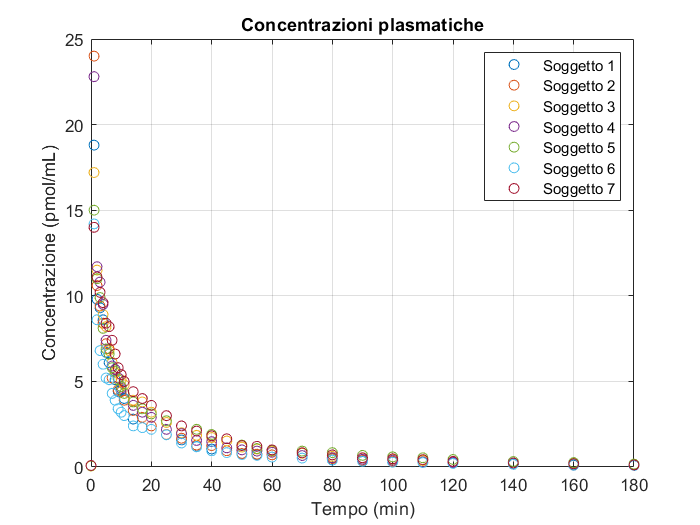

% Plot concentrazioni plasmatiche
figure(1);
plot(t1,c1,"o",t2,c2,"o",t3,c3,"o",t4,c4,"o",t5,c5,"o",t6,c6,"o",t7,c7,"o"),
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title("Concentrazioni plasmatiche"), legend("Soggetto 1","Soggetto 2","Soggetto 3","Soggetto 4", ...
"Soggetto 5","Soggetto 6","Soggetto 7")

Eliminazione della concentrazione basale e delle misure non necessarie nel fitting.

c1 = c1 - c1(1); % Eliminazione concentrazione basale
c1 = c1(3:end);  % Eliminazione misura concentrazione basale e minuto successivo
t1 = t1(3:end);  % Eliminazione misura concentrazione basale e minuto successivo (tempo)
c2 = c2 - c2(1);
c2 = c2(3:end);
t2 = t2(3:end);
c3 = c3 - c3(1);
c3 = c3(3:end);
t3 = t3(3:end);
c4 = c4 - c4(1);
c4 = c4(3:end);
t4 = t4(3:end);
c5 = c5 - c5(1);
c5 = c5(3:end);
t5 = t5(3:end);
c6 = c6 - c6(1);
c6 = c6(3:end);
t6 = t6(3:end);
c7 = c7 - c7(1);
c7 = c7(3:end);
t7 = t7(3:end);

## Stima dei parametri con Minimi Quadrati (LS) e Minimi Quadrati Pesati (WLS)

Il metodo ai Minimi Quadrati (*Least Squares*) consente di trovere i parametri `p` del modello tali che la discrepanza tra i dati *z* e le predizioni del modello *h(ti,p)* sia minima. Per far questo si utilizza il seguente funzionale di costo: 


$$J\left(p\right)=\sum_{i=1}^N {\left(z_i -y_i \right)}^2 =\sum_{i=1}^N {\left(z_i -h\left(t_i \;,p\right)\right)}^2 =\sum_{i=1}^N {e_i }^2$$
 

Bisogna percio' risolvere il seguente problema di ottimizzazione:


$$\hat{p_{\mathrm{LS}} } =\mathrm{argmin}\left(J\left(p\right)\right)$$


In modo analogo si definisce il funzionale di costo per i Minimi Quadrati Pesati (*Weighted Least Squares*) considerando la matrice dei pesi *W = diag(w1,w2,...,wn)*:


$$J_W \left(p\right)={|\left|z-H\left(p\right)\right|\left|\right.}^2 =\sum_{i=1}^N {{w_i e}_i }^2 \;\left(p\right)$$


in cui l'errore *ei* ha peso differente sei i *wi *sono diversi tra loro. Ancora una volta e' necessario risolvere il seguente problema di ottimizzazione: 


$$\hat{p_{\mathrm{WLS}} } =\mathrm{argmin}\left(J_W \left(p\right)\right)\;$$


Quando la funzione h che determina l'uscita predetta dal modello non e' lineare, il problema non e' risolvibile in forma chiusa ed e' necessario ricorrere a metodi iterativi (in Matlab si usa la funzione `lsqnonlin`). 

## Fitting di modelli ingresso uscita a 1,2,3 esponenziali

Segue il fitting dei modelli ingresso uscita con Minimi Quadrati e Minimi Quadrati Pesati per uno specifico paziente.

selectedSogg = "Soggetto6"; % Selezione del soggetto 
switch selectedSogg
    case "Soggetto1"
        c = c1;
        t = t1;
    case "Soggetto2"
        c = c2;
        t = t2;
    case "Soggetto3"
        c = c3;
        t = t3;
    case "Soggetto4"
        c = c4;
        t = t4;
    case "Soggetto5"
        c = c5;
        t = t5;
    case "Soggetto6"
        c = c6;
        t = t6;
    case "Soggetto7"
        c = c7;
        t = t7;
end

### Fitting modello ingresso uscita mono-esponenziale con LS e WLS

Come precedentemente detto i parametri *p* ottimali del modello si ottengono risolvendo i problemi di ottimizzazione tramite la funzione `lsqnonlin.` 

Nota: 

- `@funzionale` : handle della funzione che definisce il funzionale di costo J(p);

- `p0` : parametri iniziali per l'algoritmo di ricerca;

- `options` : opzioni di visualizzazione; 

- `t`, `c`, `1` : sono i parametri della funzione `funzionale. `

#### `LS - Modello monoesponenziale`

p0 = [18.72,0.7]; % Parametri iniziali
options = optimoptions('lsqnonlin','Display','iter');
[x1_ls,resnorm1_ls,residual1_ls,~,~,~,jacobian1_ls] = lsqnonlin(@funzionale,p0,[],[],options,t,c,1); % LS 1-exp


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          3         183.253                           117
     1          6         183.253             10            117      
     2          9         183.253            2.5            117      
     3         12         183.253       0.705365            117      
     4         15         139.884        0.15625            162      
     5         18         44.5164         0.3125           71.2      
     6         21         40.5165          0.625           6.32      
     7         24         34.6503           1.25           18.5      
     8         27          23.598            2.5           47.6      
     9         30         9.80333        5.59233            149      
    10         33         7.10855       0.109778           5.94      
    11         36         7.03835       0.210856           5.63      
    12         39         7.0289

Seguono plot in scala naturale e in scala logaritmica del fit.

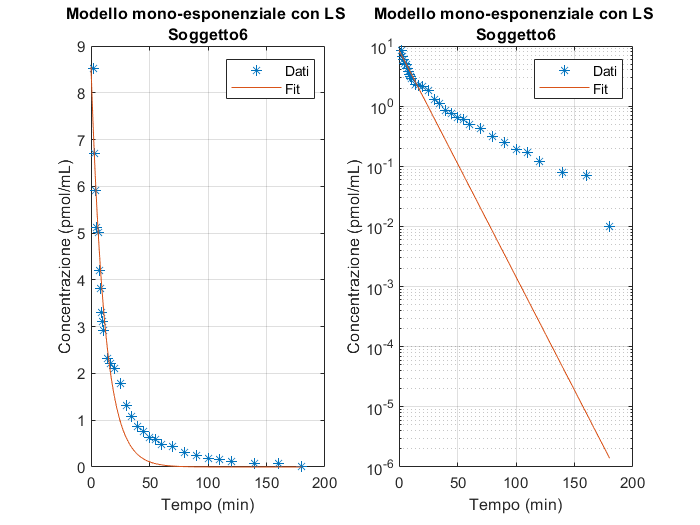

figure(2);
% Plot scala naturale
t_ls = [0:0.001:t1(end)];
plot(t,c,"*"); hold on, plot(t_ls,x1_ls(1)*exp(-x1_ls(2)*t_ls)),
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title(["Modello mono-esponenziale con LS ",selectedSogg]), legend("Dati","Fit"); 
% Plot scala logaritmica
subplot(1,2,1,gca)
subplot(1,2,2), semilogy(t,c,"*"); hold on,  semilogy(t_ls,x1_ls(1)*exp(-x1_ls(2)*t_ls)), 
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on, 
title(["Modello mono-esponenziale con LS ",selectedSogg]), legend("Dati","Fit");

disp(["Parametri LS 1-exp: A = ",num2str(x1_ls(1))," alpha = ",num2str(x1_ls(2))]); % Stampa dei parametri del fitting

    "Parametri LS 1-exp: A = "    "8.5536"    " alpha = "    "0.086807"



Analisi dei residui.

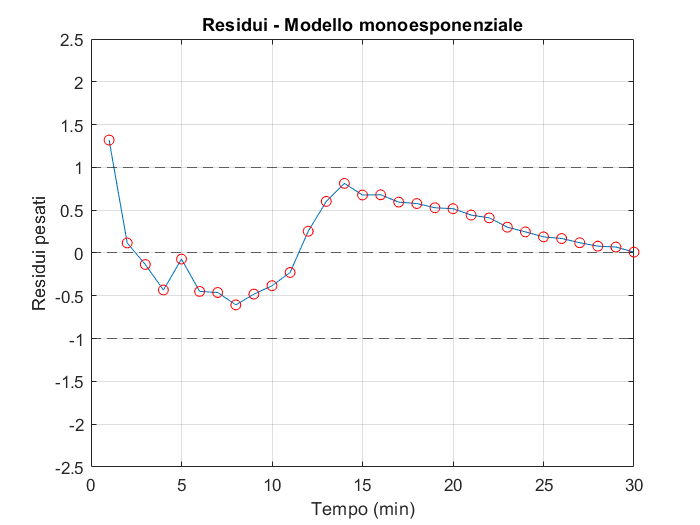

figure(3);
plot(residual1_ls,"-o","MarkerIndices",1:1:length(residual1_ls),"MarkerEdgeColor","r"), grid on, 
xlabel("Tempo (min)"), ylabel("Residui pesati"), ylim([-2.5,2.5]), title("Residui - Modello monoesponenziale"),
yline(-1,"--"); yline(1,"--"); yline(0,"--");

#### `LS - Modello con due esponenziali`

p0 = [18.72,0.7,20,0.1]; % Parametri iniziali
options = optimoptions('lsqnonlin','Display','iter');
[x2_ls,resnorm2_ls,residual2_ls,~,~,~,jacobian2_ls] = lsqnonlin(@funzionale,p0,[],[],options,t,c,2); % LS 2-exp


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          5         564.101                      4.19e+03
     1         10         85.8334             10            513      
     2         15         85.8334        22.8809            513      
     3         20          47.029              5            134      
     4         25         44.3316             10           62.9      
     5         30         40.0365            2.5             18      
     6         35         39.9444            2.5            3.8      
     7         40         39.9399              5           2.39      
     8         45         39.8776             10             13      
     9         50         39.8372             20           2.53      
    10         55         39.8324             40            2.4      
    11         60         20.6543         10.215            277      
    12         65         8.0345

Seguono plot in scala naturale e in scala logaritmica del fit.

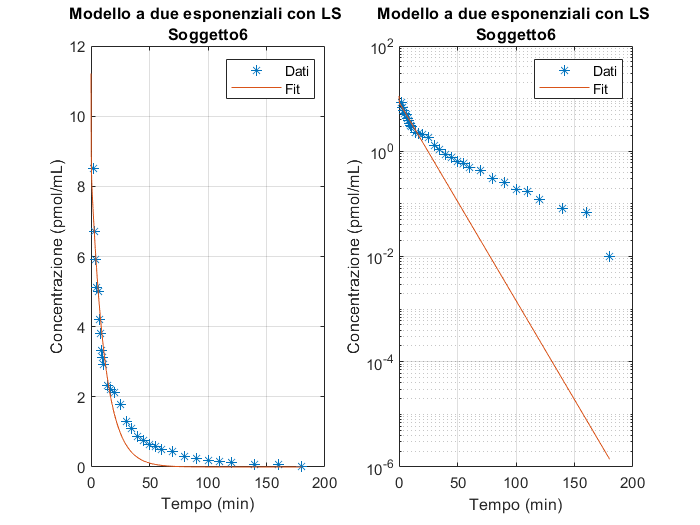

figure(4);
% Plot scala naturale
t_ls = [0:0.001:t1(end)];
plot(t,c,"*"); hold on, plot(t_ls,x2_ls(1)*exp(-x2_ls(2)*t_ls)+x2_ls(3)*exp(-x2_ls(4)*t_ls)),
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title(["Modello a due esponenziali con LS ",selectedSogg]), legend("Dati","Fit"); 
% Plot scala logaritmica
subplot(1,2,1,gca)
subplot(1,2,2), semilogy(t,c,"*"); hold on,  semilogy(t_ls,x2_ls(1)*exp(-x2_ls(2)*t_ls)+x2_ls(3)*exp(-x2_ls(4)*t_ls)), 
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on, 
title(["Modello a due esponenziali con LS ",selectedSogg]), legend("Dati","Fit");

disp(["Parametri LS 2-exp: A = ",num2str(x2_ls(1))," alpha = ",num2str(x2_ls(2))," B = ",num2str(x2_ls(3))," beta = ",num2str(x2_ls(4))]); % Stampa dei parametri del fitting

    "Parametri LS 2-ex…"    "8.5516"    " alpha = "    "0.086765"    " B = "    "2.6647"    " beta = "    "6.9188"



Analisi dei residui.

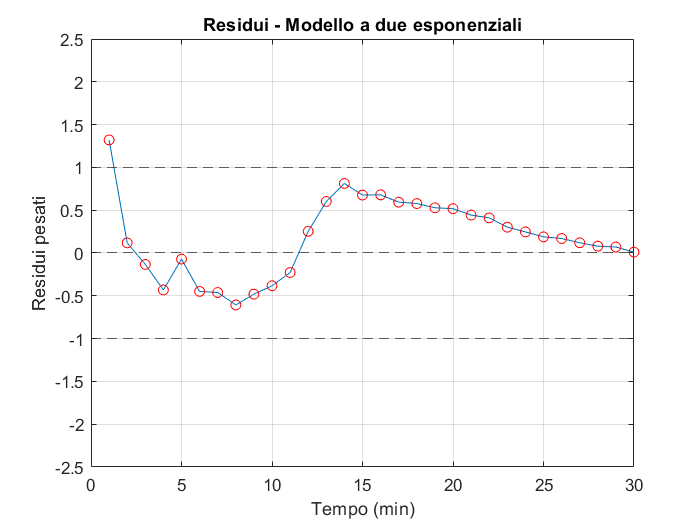

figure(3);
plot(residual2_ls,"-o","MarkerIndices",1:1:length(residual2_ls),"MarkerEdgeColor","r"), grid on, 
xlabel("Tempo (min)"), ylabel("Residui pesati"), ylim([-2.5,2.5]), title("Residui - Modello a due esponenziali"),
yline(-1,"--"); yline(1,"--"); yline(0,"--");

#### WLS - Modello monoesponenziale

CV = 0.04;          % CV
alpha = CV^2;       % alpha
B = diag(c.^2);     % B
sigma_v = alpha*B;  % Matrice SigmaV
w = inv(sigma_v);   % Matrice dei pesi

p0 = [18.72,0.5]; % Parametri iniziali
options = optimoptions('lsqnonlin','Display','iter');
[x1_wls,resnorm1_wls,residual1_wls,~,~,~,jacobian1_wls] = lsqnonlin(@funzionalew,p0,[],[],options,t,c,1,sqrt(w)); % LS 1-exp


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          3         16226.4                      4.23e+03
     1          6         16226.4             10       4.23e+03      
     2          9         16226.4            2.5       4.23e+03      
     3         12         16226.4          0.625       4.23e+03      
     4         15         14378.8        0.15625       7.89e+03      
     5         18         11909.5         0.3125       6.34e+03      
     6         21         11671.5          0.625       1.42e+03      
     7         24         11349.5           1.25       1.73e+03      
     8         27         10647.4            2.5       6.98e+03      
     9         30         8516.89              5       3.32e+04      
    10         33         8516.89         5.4725       3.32e+04      
    11         36         5282.74        1.36812        5.2e+04      
    12         39         2110.5

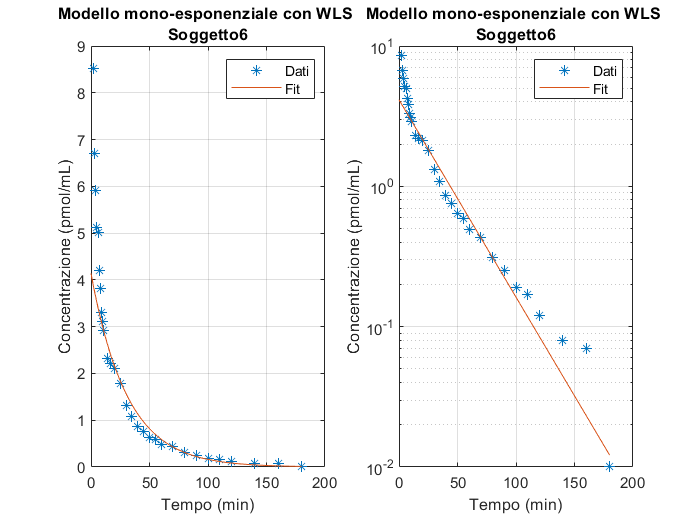

figure(6);
% Plot scala naturale
t_ls = [0:0.001:t1(end)];
plot(t,c,"*"); hold on, plot(t_ls,x1_wls(1)*exp(-x1_wls(2)*t_ls)),
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title(["Modello mono-esponenziale con WLS ",selectedSogg]), legend("Dati","Fit"); 
% Plot scala logaritmica
subplot(1,2,1,gca)
subplot(1,2,2), semilogy(t,c,"*"); hold on,  semilogy(t_ls,x1_wls(1)*exp(-x1_wls(2)*t_ls)), 
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on, 
title(["Modello mono-esponenziale con WLS ",selectedSogg]), legend("Dati","Fit");

disp(["Parametri WLS 1-exp: A = ",num2str(x1_wls(1))," alpha = ",num2str(x1_wls(2))]); % Stampa dei parametri del fitting

    "Parametri WLS 1-exp: A = "    "4.1373"    " alpha = "    "0.032383"



Analisi dei residui.

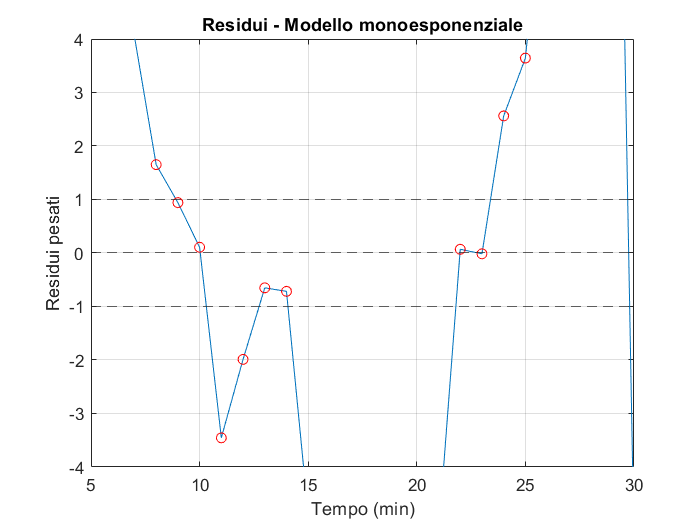

figure(7);
plot(residual1_wls,"-o","MarkerIndices",1:1:length(residual1_wls),"MarkerEdgeColor","r"), grid on, 
xlabel("Tempo (min)"), ylabel("Residui pesati"), ylim([-4,4]), title("Residui - Modello monoesponenziale"),
yline(-1,"--"); yline(1,"--"); yline(0,"--");

#### `WLS - Modello con due esponenziali`

p0 = [18.72,0.7,20,0.1]; % Parametri iniziali
options = optimoptions('lsqnonlin','Display','iter');
[x2_wls,resnorm2_wls,residual2_wls,~,~,~,jacobian2_wls] = lsqnonlin(@funzionalew,p0,[],[],options,t,c,2,sqrt(w)); % LS 2-exp


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          5         21171.2                       1.3e+05
     1         10         14113.1             10       3.22e+04      
     2         15         14113.1             20       3.22e+04      
     3         20         13669.4              5       1.71e+04      
     4         25         12595.9           1.25       9.76e+03      
     5         30         11626.8            2.5       1.05e+04      
     6         35         7895.08              5       7.15e+04      
     7         40         7895.08        11.5524       7.15e+04      
     8         45         7895.08            2.5       7.15e+04      
     9         50         7895.08          0.625       7.15e+04      
    10         55         7895.08        0.15625       7.15e+04      
    11         60         7895.08      0.0390625       7.15e+04      
    12         65         6202.3

Seguono plot in scala naturale e in scala logaritmica del fit.

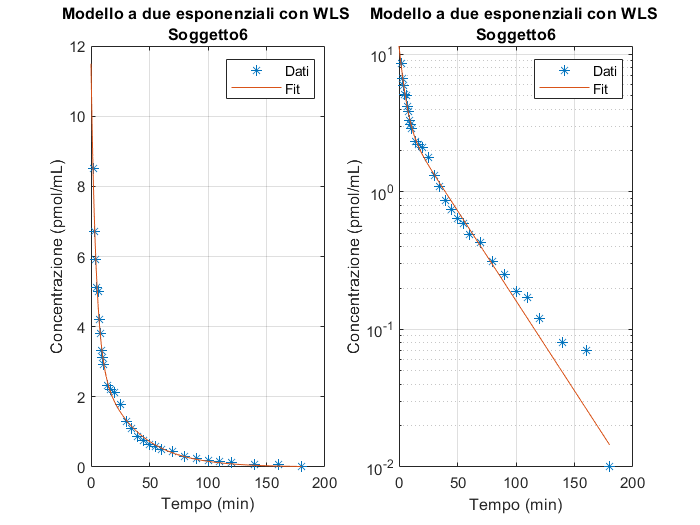

figure(8);
% Plot scala naturale
t_ls = [0:0.001:t1(end)];
plot(t,c,"*"); hold on, plot(t_ls,x2_wls(1)*exp(-x2_wls(2)*t_ls)+x2_wls(3)*exp(-x2_wls(4)*t_ls)),
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title(["Modello a due esponenziali con WLS ",selectedSogg]), legend("Dati","Fit"); 
% Plot scala logaritmica
subplot(1,2,1,gca)
subplot(1,2,2), semilogy(t,c,"*"); hold on,  semilogy(t_ls,x2_wls(1)*exp(-x2_wls(2)*t_ls)+x2_wls(3)*exp(-x2_wls(4)*t_ls)), 
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on, 
title(["Modello a due esponenziali con WLS ",selectedSogg]), legend("Dati","Fit");

disp(["Parametri LS 2-exp: A = ",num2str(x2_wls(1))," alpha = ",num2str(x2_wls(2))," B = ",num2str(x2_wls(3))," beta = ",num2str(x2_wls(4))]); % Stampa dei parametri del fitting

    "Parametri LS 2-ex…"    "8.1942"    " alpha = "    "0.24345"    " B = "    "3.2997"    " beta = "    "0.030155"



Analisi dei residui.

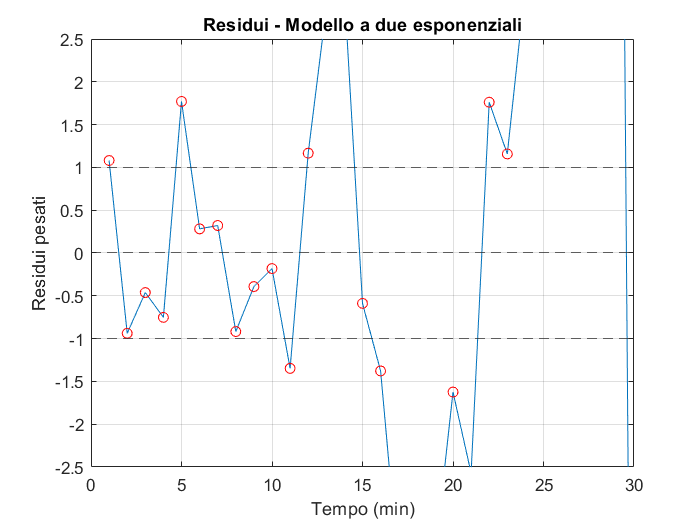

figure(9);
plot(residual2_wls,"-o","MarkerIndices",1:1:length(residual2_wls),"MarkerEdgeColor","r"), grid on, 
xlabel("Tempo (min)"), ylabel("Residui pesati"), ylim([-2.5,2.5]), title("Residui - Modello a due esponenziali"),
yline(-1,"--"); yline(1,"--"); yline(0,"--");